# ECEN5463 | HW 3

Collin Thornton

## Problem 1

Young's inequality states that for all $p>1$ and $q>1$ that satisfy $\left(p-1\right)\left(q-1\right)=1$, all $\lambda >0$, and all $x,y\in R$, it is true that


$$\textrm{xy}\le \frac{\lambda^p }{p}|x|^p +\frac{1}{q\lambda {\;}^q }|y|^q$$


### 1.1 Use Young's inequality to show that $x^m y^n$ can be expressed as the following for appropriate choices of $w_1 ,\ldotp \ldotp \ldotp ,w_4$.

#### 1.1.1  $x^m y^n \le w_1 x^{2m} +w_2 y^{2n}$


$$x^m y^n \le w_1 x^{2m} +w_2 y^{2n} =\frac{\lambda^p }{p}|x^m |^p +\frac{1}{q\lambda {\;}^q }|y^n |^q$$



$$w_1 x^{2m} +w_2 y^{2n} =\frac{\lambda^p }{p}|x|^{\textrm{mp}} +\frac{1}{q\lambda^q }|y|^{\textrm{nq}}$$


Take $p=2,q=2$   $\to$   Check $\left(2-1\right)\left(2-1\right)=1$ (pass)


$$w_1 x^{2m} +w_2 y^{2n} =\frac{\lambda^2 }{2}|x|^{2m} +\frac{1}{2\lambda^2 }|y|^{2n}$$


***Note:*** $x,y$ are raised to the power of an even number. The absolute value can be dropped.


$$w_1 x^{2m} +w_2 y^{2n} =\frac{\lambda^2 }{2}x^{2m} +\frac{1}{2\lambda^2 }y^{2n}$$


Therefore, $\;x^m y^n \le w_1 x^{2m} +w_2 y^{2n}$ is true for $w_1 =\frac{\lambda^2 }{2}$ and $w_2 =\frac{1}{2\lambda^2 }$  

#### 1.1.2 $x^m y^n \le w_3 |x|^{m+n} +w_4 |y|^{m+n}$


$$w_3 {|x|}^{m+n} +w_4 |{y|}^{m+n} =\frac{\lambda^p }{p}|x^m |^p +\frac{1}{q\lambda {\;}^q }|y^n |^q$$



$$w_3 {|x|}^{m+n} +w_4 |{y|}^{m+n} =\frac{\lambda^p }{p}|x|^{\textrm{mp}} +\frac{1}{q\lambda {\;}^q }|y|^{\textrm{nq}}$$



$$mp=m+n$$
    
$$nq=m+n$$


$p=\frac{n}{m}+1$      $q=\frac{m}{n}+1$  $\to$  Check $\left(\frac{n}{m}+1-1\right)\left(\frac{m}{n}+1-1\right)=0$ (pass)


$$w_3 |x|^{m+n} +w_4 |y|^{m+n} =\frac{\lambda^{\frac{n}{m}+1} }{\frac{n}{m}+1}|x|^{n+m} +\frac{1}{\left(\frac{m}{n}+1\right)\lambda^{\frac{m}{n}+1} }|y|^{n+m}$$


Therefore, $x^m y^n \le w_3 |x|^{m+n} +w_4 |y|^{m+n}$ is true for $w_3 =\frac{\lambda^{\frac{n}{m}+1} }{\frac{n}{m}+1}$ and $w_4 =$$\frac{\lambda^{-\frac{m}{n}-1} }{\frac{m}{n}+1}$ where $mn>0$

### 1.2 Use Lyapunov's direct method to show that the following systems, with $x,y\in \mathbb{R}$, have a GAS equilibrium point at the origin of $\mathbb{R}^2$

#### 1.2.1 $\dot{x} =-x+y^3$ and $\dot{y} =-y$


$$f\left(x,y\right)=\left\lbrack \begin{array}{c}
-x+y^3 \\
-y
\end{array}\right\rbrack$$


Choose $V\left(x,y\right)={\textrm{ax}}^2 +{\textrm{by}}^6$


$$\dot{V} \left(x,y\right)=\left\lbrack \begin{array}{cc}
\frac{\partial V\left(x,y\right)}{\partial x} & \frac{\partial V\left(x,y\right)}{\partial y}
\end{array}\right\rbrack f\left(x,y\right)$$



$$\dot{V} \left(x,y\right)=\left\lbrack \begin{array}{cc}
2\textrm{ax} & 6{\textrm{by}}^5 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
-x+y^3 \\
-y
\end{array}\right\rbrack =-2{\textrm{ax}}^2 +2{\textrm{axy}}^3 -6{\textrm{by}}^6$$


Note that terms 1 and 3 of the RHS are negative definite. We now need to prove that term 2 of the RHS has a smaller impact.

By  Young's equation


$$2{\textrm{axy}}^3 \le 2a\frac{\lambda }{2}x^2 +2a\frac{\lambda^{-2} }{2}y^6 =2{\textrm{ax}}^2 +6{\textrm{by}}^6$$


First term of RHS shows $\lambda =\sqrt{2}$  (is valid as $\lambda >0$)

Second term of RHS shows $\frac{a}{\lambda^2 }=6b$ $\to \frac{a}{b}=12$

Thus, any $V\left(x\right)={\textrm{ax}}^2 +{\textrm{by}}^6$ will show GAS iff $\frac{a}{b}=12$ as Young's equation holds $x,y \in \mathbb{R}$

#### 1.2.2 $\dot{x} =-x^3 +y^3$ and $\dot{y} =-y$


$$f\left(x,y\right)=\left\lbrack \begin{array}{c}
-x^3 +y^3 \\
-y
\end{array}\right\rbrack$$


First guess: let's assume $V\left(x,y\right)={\textrm{ax}}^2 +{\textrm{by}}^2$


$$\dot{V} \left(x,y\right)=\left\lbrack \begin{array}{cc}
2\textrm{ax} & 2\textrm{by}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
-x^3 +y^3 \\
-y
\end{array}\right\rbrack =-2{\textrm{ax}}^4 +2{\textrm{axy}}^3 -2{\textrm{by}}^2$$


Again, we need to show that the second term of the RHS has a smaller impact than the first and third terms, or:


$$2{\textrm{axy}}^3 \le -2{\textrm{ax}}^4 +2{\textrm{by}}^2$$


This is compatible with the second version of Young's equation, so we need to express $V\left(x,y\right)$ in such a way that $\dot{V} \left(x,y\right)$ is of the form $-2{\textrm{ax}}^{n+m} +2{\textrm{ax}}^m y^n -2{\textrm{by}}^{n+m}$.

This can be achieved by setting $V\left(x,y\right)={\textrm{ax}}^2 +{\textrm{by}}^4$

Now, $\dot{V} \left(x,y\right)=\left\lbrack \begin{array}{cc}
2\textrm{ax} & 4{\textrm{by}}^3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
-x^3 +y^3 \\
-y
\end{array}\right\rbrack =-2{\textrm{ax}}^4 +2{\textrm{axy}}^3 -4{\textrm{by}}^4$

Plugging into Young's equation: $2{\textrm{axy}}^3 \le 2{\textrm{ax}}^4 +4{\textrm{by}}^4$

Simplify: ${\textrm{xy}}^3 \le x^4 +2\frac{b}{a}y^4$

Thus, $w_3 =\frac{\lambda^{\frac{n}{m}+1} }{\frac{n}{m}+1}=1$ and $w_4 =\frac{\lambda^{-\frac{m}{n}-1} }{\frac{m}{n}+1}=2\frac{b}{a}$


$$1=\frac{\lambda^4 }{4}\to \lambda =4^{\frac{1}{4}}$$



$$\frac{b}{a}=\frac{1}{2}\frac{3}{4\lambda^{\frac{4}{3}} }=\frac{3}{{8*4}^{\frac{1}{4}*\frac{4}{3}} }=\frac{3}{8\sqrt[3]{4}}$$


As $m,n>0$ and $\lambda >0$, this relationship is valid for all $x,y\in \mathbb{R}$

Thus, taking any $V\left(x,y\right)={\textrm{ax}}^2 +{\textrm{by}}^4$, where $\frac{b}{a}=\frac{3}{8\sqrt[3]{4}}$  will show GAS as Young's equation holds for all $x,y\in\mathbb{R}$.

## Problem 2

For the two-link robot model:


$$M\left(q\right)\ddot{q} +V_m \left(q,\dot{q} \right)\dot{q} +F_s \left(\dot{q} \right)+F_d \dot{q} =\tau$$


let the tracking error be defined as

$e=\left\lbrack \begin{array}{c}
q_{\textrm{d1}} -q_1 \\
q_{\textrm{d2}} -q_2 
\end{array}\right\rbrack$, where $q_{\textrm{d1}} =\frac{20}{3}\textrm{pi}$ rad and $q_{\textrm{d2}} =\frac{10}{3}\textrm{pi}$ rad.

Design a controller such that the tracking error goes to zero as time goes to infinity. Prove that your controller achieves the desired objective **without using LaSalle's invariance principle.**

$M\left(q\right)=\left\lbrack \begin{array}{cc}
p_1 +2p_3 \cos \left(q_2 \right) & p_2 +p_3 \cos \left(q_2 \right)\\
p_2 +p_3 \cos \left(q_2 \right) & p_2 
\end{array}\right\rbrack$ and $V_m \left(q,\dot{q} \right)=\left\lbrack \begin{array}{cc}
-p_3 \sin \left(q_2 \right)\dot{q}  & -p_3 \sin \left(q_2 \right)\left(\dot{q_1 } +\dot{q_2 } \right)\\
p_3 \sin \left(q_2 \right)\dot{q_1 }  & 0
\end{array}\right\rbrack$

$F_s \left(\dot{q} \right)=\left\lbrack \begin{array}{c}
8\ldotp 45\tanh \left(\dot{q_1 } \right)\\
2\ldotp 35\tanh \left(\dot{q_2 } \right)
\end{array}\right\rbrack$and $F_d \left\lbrack \begin{array}{cc}
f_{\textrm{d1}}  & 0\\
0 & f_{\textrm{d2}} 
\end{array}\right\rbrack$

Convert to state space form:


$$f\left(x\right)=\left\lbrack \begin{array}{c}
\dot{q} \\
{-M}^{-1} \left(q\right)\left(V_m \left(q,\dot{q} \right)\dot{q} +F_s \left(\dot{q} \right)+F_d \dot{q} -\tau \;\right)
\end{array}\right\rbrack$$


Implementing a PD controller, where $\tau =k_p e+k_d \dot{e}$, where $k_p ,k_d \succ 0$ and are diagonal


$$f\left(x\right)=\left\lbrack \begin{array}{c}
\dot{q} \\
{-M}^{-1} \left(q\right)\left(V_m \left(q,\dot{q} \right)\dot{q} +F_s \left(\dot{q} \right)+F_d \dot{q} -\left(k_p e+k_d \dot{e} \right)\;\right)
\end{array}\right\rbrack$$


Rewriting with the state in terms of the error: $x={\left\lbrack \begin{array}{cc}
e & \dot{e} 
\end{array}\right\rbrack }^T$ modifies the dynamical system to


$$-M\left(q_d -x_1 \right)\ddot{e} -V_m \left(q_d -x_1 ,-x_2 \right)x_2 +F_s \left(-x_2 \right)-F_d x_2 =k_p x_1 +k_d x_2$$



$$f\left(x\right)=\left\lbrack \begin{array}{c}
x_2 \\
{-M}^{-1} \left(q_d -x_1 \right)\left(V_m \left(q_d -x_1 ,-x_2 \right)x_2 -F_s \left(-x_2 \right)+F_d x_2 +k_p x_1 +k_d x_2 \;\right)
\end{array}\right\rbrack$$


I'll sub in $e,\dot{e} ,\;q$ and $\dot{q}$ throughtout the algebra to reduce notation.

Pick a $V\left(x\right)$ which is positive definite and continuous:


$$V(x)=\frac{1}{2}e^Tk_pe+\frac{1}{2}\dot e^TM(q)\dot e$$


Now, compute $\dot{V} \left(x\right)$ and determine system stability


$$\frac{\partial V(x)}{\partial x}= \left [ e^Tk_p+\frac{1}{2}\dot e^T \frac{\partial(M(q)\dot e)}{\partial e}, ~\dot e^TM(q)\right ]$$



$$\dot{V} \left(x\right)=\frac{\partial V\left(x\right)}{\partial x}f\left(x\right)=\left(e^T k_P +\frac{1}{2}{\dot{e} }^T \frac{\partial \left(M\left(q\right)\dot{e} \right)\;}{\partial e}\right)\dot{e} +\left({\dot{e} }^T M\left(q\right)\right)\left({-M}^{-1} \left(q\right)\left(V_m \left(q,\dot{q} \right)\dot{e} -F_s \left(\dot{q} \right)+F_d \dot{e} +k_p e+k_d \dot{e} \;\right)\right)$$



$$\dot{V} \left(x\right)=e^T k_p \dot{e} +\frac{1}{2}{\dot{e} }^T \frac{\partial M\left(q\right)\dot{e} }{\partial e}\dot{e} -{\dot{e} }^T V_m \left(q,\dot{q} \right)\dot{e} +{\dot{e} }^T F_s \left(\dot{q} \right)-{\dot{e} }^T F_d \dot{e} -{\dot{e} }^T k_p e-{\dot{e} }^T k_d \dot{e}$$



$$\dot{V} \left(x\right)={\dot{e} }^T \left(\frac{1}{2}\frac{\partial M\left(q\right)\dot{e} }{\partial e}-V_m \left(q,\dot{q} \right)-F_d -k_d \right)\dot{e} +{\dot{e} }^T F_s \left(\dot{q} \right)+e^T k_p \dot{e} -{\dot{e} }^T k_p e$$
 

By skew symmetry of $\frac{1}{2}\frac{\partial M\left(q\right)\dot{e} }{\partial e}-V_m \left(q,\dot{q} \right)$ and symmetry of $k_p$


$$\dot{V} \left(x\right)=-{\dot{e} }^T F_d \dot{e} -{\dot{e} }^T k_d \dot{e} +{\dot{e} }^T F_s \left(\dot{q} \right)+e^T \left(k_p -k_p \right)\dot{e}$$



$$\dot{V} \left(x\right)=-{\dot{e} }^T F_d \dot{e} -{\dot{e} }^T k_d \dot{e} -{\dot{e} }^T F_s \left(\dot{e} \right)$$


$\dot{V} \left(e,\dot{e} \right)=-{\dot{e} }^T F_d \dot{e} -{\dot{e} }^T k_d \dot{e} -{\dot{e} }^T F_s \left(\dot{e} \right)\succeq 0$ is positive semidefinite and remains $0$ on the line $\dot{e} =0$. From here, we can directly conclude **Lyupanov stability**. A conclusion of global asymptotic stability requires further analysis.

As $\dot{V} \left(x\right)=0$ on the line $\dot{e} =0$. From this, we infer that $V\left(x\right)$is strictly decreasing for all $\dot{e} \;\not= \;0$. This implies that $\dot{e}$ must tend toward 0 as $t\to \infty$; otherwise $V\left(x\right)$ would eventually become negative. Furthermore, this implies that $e$ must tend toward a constant $c$ as $t\to \infty$.

In order for $\dot{e} \left(t\right)$to tend toward and remain at 0, $\ddot{e} \left(t\right)$ must also tend toward 0. Otherwise, $\dot{e} \left(t\right)$will eventually leave the origin.

Looking at the dynamics:


$$-M\left(q\right)\ddot{e} -V_m \left(q,\dot{q} \right)\dot{e} +F_s \left(\dot{q} \right)-F_d \dot{e} =k_p e+k_d \dot{e}$$
 

Set $\dot{e}$ and $\ddot{e}$ to $0$


$$-M\left(q\right)\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack -V_m \left(q,\dot{q} \right)\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack +F_s \left(\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \right)-F_d \left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack =k_p e+k_d \left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


This is equation is only valid if $e=\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$, assuming both $\dot{e}$ and $\ddot{e}$ are zero. This remains true regardless of inital conditions, so we can conclude **global asymptotic stability** at $x=0$.

## Problem 3

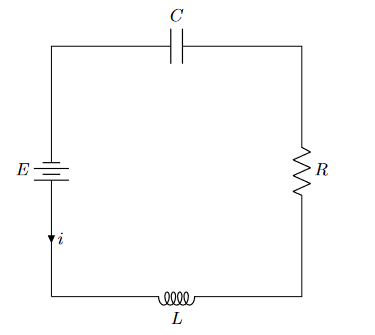

Consider the RLC circuit shown above. If the voltage applied to the circuit is zero then the dynamics can be expressed as 

$\ddot{q} +\frac{R}{L}\dot{q} +\frac{1}{\textrm{LC}}q=0$.

Express the model in state space from so that the oriign is an equilibrium point. Then, use Lyapunov's direct method (or the invariance principle) to get the best possible statbility result you can for the equiplibrium point at the origin. Can you show global asymptotic stability?

**Physical Analysis:** The resistance of the system immediately implies GAS, as the resistor will always dissipate energy. The indicates that the current $\dot{q}$, and by extension $\ddot{q}$, will approach $0$ as $t\to \infty$. If both $\ddot{q}$ and $\dot{q}$ are zero, then $q$ must be zero to satisfy the system dynamics.

### 3.1 Express the model in state space form


$$\ddot{\;q} =-\frac{R}{L}\dot{q} -\frac{1}{\textrm{LC}}q$$


Define state $x={\left\lbrack q\;\dot{\;q} \right\rbrack }^T$

$\dot{x} =\left\lbrack \begin{array}{c}
\dot{q} \\
-\frac{R}{L}\dot{q} -\frac{1}{\textrm{LC}}q
\end{array}\right\rbrack =\textrm{Ax}+\textrm{Bu}$, where $u=E=0$


$$A=\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{1}{\textrm{LC}} & -\frac{R}{L}
\end{array}\right\rbrack$$


State space model:


$$f\left(x\right)=\dot{x} =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{1}{\textrm{LC}} & -\frac{R}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
q\\
\dot{q} 
\end{array}\right\rbrack$$


Analyze equilibrium points:

syms R L C q dq

x = [q; dq];
A = [0, 1; -1/(L*C) -R/L];

f = A*x;
sol = solve(f == 0);

eq_points = [sol.q, sol.dq]

$$eq\_points = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

### 3.2 Use Lyapunov's direct method or the invariance to find the best possible stability result

Let us define $V\left(x\right)$with respect to the total energy of the circuit.

First, prove hypothesis:

1.) We've already proved the origin is an equilibrium point

2.) Local Lipschitz continuity, ie for all $x\in D$, there exist two numbers $L,\sigma >0$ such that

$\forall \;z,y\in B\left(x,\sigma \right)$ and $\forall \;t\in I$,     $||f\left(t,z\right)-f\left(t,y\right)||\le L||z-y||$

$f\left(x\right)=\left\lbrack \begin{array}{c}
\dot{q} \\
-\frac{q}{\textrm{LC}}-\frac{R}{L}\dot{q} 
\end{array}\right\rbrack$ is differentiable and its derivative is locally bounded. That is, the norm of its Jacobian is bounded. As $A=\;\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{1}{\textrm{LC}} & -\frac{R}{L}
\end{array}\right\rbrack$, it can be seen that $||A||$ is is bounded for all $x$, indicating that $f\left(x\right)$is not only locally Lipschitz, but also globally Lipschitz.

Energy in capacitor: $U_C =\frac{q^2 }{2C}$

Energy in inductor:  $U_L =\frac{1}{2}L{\dot{q} }^2$

Resistor doesn't store energy, only dissipates

Thus: $V\left(x\right)=\frac{q^2 }{2C}+\frac{L{\dot{q} }^2 }{2}$

$V\left(x\right)$is positive definite and continuously differentiable.

V = q^2/(2*C) + L*dq^2/2;

dv = simplify(transpose(gradient(V, x))*f)

$$dv = -R\,{\mathrm{dq}}^{2}$$


$$\dot{V} \left(x\right)=\frac{\partial \;V\left(x\right)}{\partial \;x}f\left(x\right)=\left\lbrack \begin{array}{cc}
\frac{q}{C} & L\dot{q} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{1}{\textrm{LC}} & -\frac{R}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
q\\
\dot{q} 
\end{array}\right\rbrack =-R{\dot{q} }^2$$


As $\dot{V} \left(x\right)\preceq 0$ (is negative semidefinite), we can conlude Lyupanov stability at the origin.

Now, we can either try a different Lyupanov candidate function, try the invariance method, or take another look at the dynamics.

$\dot{V} \left(x\right)=0$ on the line $\dot{q} =0$. From this, we infer that $V\left(x\right)$is strictly decreasing for all $\dot{q} \;\not= \;0$. This implies that $\dot{q}$ must tend toward 0 as $t\to \infty$; otherwise $V\left(x\right)$ would eventually become negative.

In order for $\dot{q} \left(t\right)$to tend toward and remain at 0, $\ddot{q} \left(t\right)$ must also tend toward 0. Otherwise, $\dot{q} \left(t\right)$will eventually leave the origin. In compliance with the dynamics $\ddot{q} +\frac{R}{L}\dot{q} +q=0$, $q$ must settle at 0 if both $\dot{q}$ and $\ddot{q}$ are zero.

This remains true regardless of inital conditions, so we can conclude global asymptotic stability of $x=0$.

## Problem 4

Consider the control system $\dot{x} =f\left(x\right)+g\left(x\right)u$ where $f: \mathbb{R}^n\rightarrow\mathbb{R}^n$ and $g: \mathbb{R}^n\rightarrow\mathbb{R}^m$ are such that there exists a continuously differentiable, positive definite, radially unbounded function $V: \mathbb{R}^n\rightarrow\mathbb{R}_{\geq0}$ satisfying $\frac{\partial V\left(x\right)}{\partial x}f\left(x\right)\le 0$   $\forall x\in \mathbb{R}$ and such that the origin of 


$$\dot{x} =f\left(x\right)$$



$$y=g^T \left(x\right){\left(\frac{\partial V\left(x\right)}{\partial x}\right)}^T$$


is detectable, i.e., $y\left(t\right)=0,\forall t$ implies $\lim_{t\to \infty } x\left(t\right)=0$. Design the controller $k: \mathbb{R}^n\rightarrow\mathbb{R}^m$ so that the dynamic feedback $\dot{u} =-u-k\left(x\right)$ renders the origin of the $\left(x;u\right)$ system globally asympotitcally stable. Explain why your controller works using a Lyapunov analysis, perhaps with the relaxed conditions that come from the invariance principle.

Let $z=\left\lbrack \begin{array}{c}
x\\
u
\end{array}\right\rbrack$ and $W\left(z\right)=\frac{1}{2}u^T u+V\left(x\right)$

Now, let the system be $h\left(z\right)=\dot{z} =\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{u} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f\left(x\right)+g\left(x\right)u\\
-u-k\left(x\right)
\end{array}\right\rbrack$

We need to first satisfy the hypotheses of the Lyapunov theorem

**1.) Find a set **$D\subset\mathbb{R}^n$ **is an open and connected set containing the origin**

We'll get back to this one later

**2.) Show that **$h\left(0\right)=0$

Adds the constraint that $f\left(0\right)=0$ and $k\left(0\right)=0$. 

**3.) Show that **$h\left(z\right)$ **is locally Lipschitz continuous**

$h\left(z\right)$ will be locally Lipschitz continuous if we choose $f\left(x\right),g\left(x\right),\mathrm{and}\;k\left(x\right)$to be locally Lipschitz continuous.

**4.) Show that **$W: ~D\rightarrow\mathbb{R}^n$ **is differentiable and positive definite**

Initial guess at $W\left(z\right)$:   $W\left(z\right)=\frac{1}{2}u^T u+V\left(x\right)$, which is differentiable and positive definite.

Now, we must compute $\frac{\partial W\left(z\right)}{\partial z}h\left(z\right)$ and determine whether it is negative definite, negative semidefinite, or neither.


$$\begin{array}{l}
\frac{\partial W\left(z\right)}{\partial z}h\left(z\right)=\left\lbrack \begin{array}{cc}
\frac{\partial W\left(z\right)}{\partial x} & \frac{\partial W\left(z\right)}{\partial u}
\end{array}\right\rbrack h\left(z\right)=\left\lbrack \begin{array}{cc}
\frac{\partial V\left(x\right)}{\partial x} & u^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
f\left(x\right)+g\left(x\right)u\\
-u-k\left(x\right)
\end{array}\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\frac{\partial V\left(x\right)}{\partial x}f\left(x\right)+\frac{\partial V\left(x\right)}{\partial x}g\left(x\right)u-u^T u-u^T k\left(x\right)
\end{array}$$


By the problem description, $\frac{\partial V\left(x\right)}{\partial x}f\left(x\right)$ is negative semidefinite. The term ${-u}^T u$ is negative definite. Thus, we need only show that $\frac{\partial V\left(x\right)}{\partial x}g\left(x\right)u$ and $-u^T k\left(x\right)$ are at minimum negative semidefinite so that we can apply the invariance principle. This solution also allows $D$ to span all real numbers, which will be useful in declaring the system GAS by the invariance principle.

Another approach is to set $\frac{\partial V\left(x\right)}{\partial x}g\left(x\right)u=u^T k\left(x\right)$:


$$u^T g^T \left(x\right){\left(\frac{\partial V\left(x\right)}{\partial x}\right)}^T =u^T k\left(x\right)$$



$$g^T \left(x\right){\left(\frac{\partial V\left(x\right)}{\partial x}\right)}^T =k\left(x\right)$$


Thus if $k\left(x\right)={\left(\frac{\partial V\left(x\right)}{\partial x}g\left(x\right)\right)}^T$, then $\frac{\partial W\left(z\right)}{\partial z}h\left(z\right)$ is negative semidefinite and Lyupanov analysis shows that the origin is a stable equilibrium. Let us apply the invariance principle to determine if the system is in fact GAS.

The invariance principle requires that:

**1.) **$D \subset \mathbb{R}^{n+m}$** is open, connected, and contains the origin**

**2.) The system **$h\left(x\right)$ **is locally Lipschitz and **$h\left(x\right)=0$

**3.) **$W\left(z\right)$ **is a continuously differentiable function and positive definite**

**4.) **$\dot{W} \left(z\right)=\frac{\partial W\left(z\right)}{\partial z}h\left(z\right)\le 0,\;\;\forall z\in D$

**5.) The only solution that can start in **$E$ **and stay in **$E=\left\lbrace z\in D\;\;|\;\;\frac{\partial W\left(z\right)}{\partial z}h\left(z\right)=0\right\rbrace$ **for all **$t$** is the trivial solution **$\phi \left(t,z^0 \right)=0,\;\forall t$

then the origin is LAS. In addition, if

**6.) **$D = \mathbb{R}^{n+m}$

**7.) **$W$ **is radially unbounded**

then the origin is GAS.

We've already proved 1-4. Only 5 is necessary to prove LAS.

The set $E$ is given by$E=\left\lbrace z\in \Omega \;|\;\frac{\partial V\left(x\right)}{\partial x}f\left(x\right)+\frac{\partial V\left(x\right)}{\partial x}g\left(x\right)u-u^T u-u^T k\left(x\right)=0\right\rbrace$, which is zero when $\frac{\partial V\left(x\right)}{\partial x}f\left(x\right)-u^T u=0$. Note that $k\left(x\right)$ has been designed such that the fourth term nullifies the second term. Thus

$E=\left\lbrace z\in R^{n+m} \;\;|\;\frac{\partial V\left(x\right)}{\partial x}f\left(x\right)=u^T u\right\rbrace$.

If $z^0$ is in $E$, then $\frac{\partial W\left(\phi \left(0,z^0 \right)\right)}{\partial z}h\left(\phi \left(0,z^0 \right)\right)=\frac{\mathrm{dW}\left(\phi \left(0,z^0 \right)\right)}{\mathrm{dt}}=0$. This implies that if $z^0 \in E$,  $W\left(z\right)$ remains constant, or $W\left(z^0 \right)=c,\forall t$. By the detectability assumption, $y\left(t\right)=0,\forall t$ implies $\lim_{t\to \infty } x\left(t\right)=0$. As $y\left(x\right)=k\left(x\right)=0$, $u$ must also be $0$, else $\dot{u}$ will diverge and the system will not approach $0$ as $t\to \infty$. Finally, we are left only with $\dot{x} =f\left(x\right)$ in the original dynamic system. 

Now let's look at $\frac{\partial W\left(z\right)}{\partial z}h\left(z\right)=\frac{\partial V\left(x\right)}{\partial x}f\left(x\right)+\frac{\partial V\left(x\right)}{\partial x}g\left(x\right)u-u^T u-u^T k\left(x\right)$. By the detectablity assumption, the 2nd, 3rd, and 4th terms are nullified. Thus, $\frac{\partial V\left(x\right)}{\partial x}f\left(x\right)$ must also be $0$ and the constant $c$ must be $0$.

This indicates thate only the trivial solution can start in $E$ and stay in $E$ for all $t\ldotp$ As $V$ is defined as radially unbounded in the problem definition, the origin is GAS by Corollary 90.